## Computinh biopsy targets population

### Points inside a truncated cone shaped volume for a breast holder device

## Ploting the truncated conical surface

clear, clc
% Selecting a particular breast holder data
fileCup = '\Simulink_models\Data\dataCupD.mat';%dataCupA.mat, dataCupB.mat, dataCupC.mat
holder = load(fileCup);
R_holderUpper = holder.R_upper;
R_holderLower = holder.R_lower;
H_holder = holder.H_holder;

% Truncated Cone
n = 20;%Slice number
m = 60;%points between rH y rL
h = H_holder;
r1 = R_holderUpper;%rL
r2 = R_holderLower;%rH
r0 = linspace(r2,r1,m);
th = linspace(0,2*pi,n);
[R,T] = meshgrid(r0,th) ;
X = R.*cos(T);
Y = R.*sin(T);
Z = h-h*(R-r2)/(r1-r2);
surf(X,Y,Z);

## Getting points inside the conical surface : Method 1 (old)

% Based on https://la.mathworks.com/matlabcentral/answers/353266-how-to-generate-100-random-points-inside-the-figure

% warning('off', 'MATLAB:alphaShape:DupPointsBasicWarnId');
% ConeAlpha = alphaShape(X(:), Y(:), Z(:),95);
% warning('on', 'MATLAB:alphaShape:DupPointsBasicWarnId');
% plot(ConeAlpha);
% axis([-(R_holderUpper+10),(R_holderUpper+10), -(R_holderUpper+10),(R_holderUpper+10), 0,R_holderUpper+10], 'equal');
% view(3);
% Surrounding cuboid:
%coorMin   = [0,0,0];  % Minimal x,y,z value
%coorRange = [r1, -r1, h];    % Max - Min of x,y,z value. From radius and heigh of breast holder

% Get points inside the shapes:
% maxIter = 1e6;  % Security limit
% iter    = 0;
% n       = 100;  % Number of output points
% P       = zeros(n, 3);
% iP      = 0;
% while iP < n && iter <= maxIter
%    Q = rand(1, 3) .* coorRange + coorMin;
%    if inShape(ConeAlpha, Q)
%       iP       = iP + 1;
%       P(iP, :) = Q;
%    end
%    iter = iter + 1;
% end
% if iter == maxIter  % Increase maxIter on demand:
%    error('Cannot find enough points.');
% end
% 
% % Showing points:
% plot3(P(:,1), P(:,2), P(:,3), '.');
% axis([-(r1+10),(r1+10), -(r1+10),(r1+10), 0,r1+10], 'equal');
% view(3);

% Verifyng points trought triangulization of cone
%https://blogs.mathworks.com/pick/2013/09/06/inpolyhedron/
%vertices = [X(:) Y(:) Z(:)];
%faces = delaunay([X(:) Y(:)]);%only X and Y
%ConeTri = trisurf(faces,vertices(:,1),vertices(:,2), vertices(:,3));
%in = inpolyhedron(faces,vertices,P);
%isInside = ~isnan(in);

% Saving data
%biopsyPoint1 = P;
%save '\Simulink_models\Data\biopsyData.mat' biopsyPoint1 '-append'

## Getting points inside the conical surface : Method 2

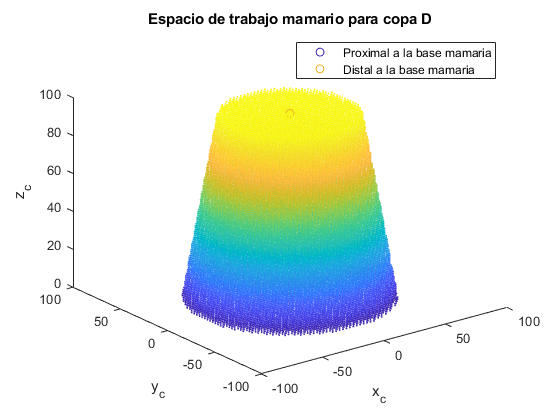

targetDataA = 0;
targetDataB = 0;
targetDataC = 0;
targetDataD = 0;
listaDatos = {targetDataA,targetDataB,targetDataC,targetDataD};
copa = {'A','B','C','D'};
for k=4:4
    if k==1
        fileCup = '\Simulink_models\Data\dataCupA.mat';
    elseif k==2
        fileCup = '\Simulink_models\Data\dataCupB.mat';
    elseif k==3
        fileCup = '\Simulink_models\Data\dataCupC.mat';
    else
        fileCup = '\Simulink_models\Data\dataCupD.mat';
    end
    
    holder = load(fileCup);
    R_holderUpper = holder.R_upper;
    R_holderLower = holder.R_lower;
    H_holder = holder.H_holder;
    
    r1 = R_holderUpper;
    r2 = R_holderLower;
    h = H_holder;
    pointNumber=50;
    step = 2*round(r1)/pointNumber;
    xvec = floor(-r1):step:ceil(r1);
    yvec = xvec;
    hvec = 0:floor(h);
    [XX, YY, HH] = ndgrid(xvec, yvec, hvec);
    r_at_H = (h-HH)*(r1-r2)/h + r2;
    is_in_cone = abs(XX) <= r1 & abs(YY) <= r1 & HH <= h & sqrt(XX.^2+YY.^2) <= r_at_H;
    Xc = XX(is_in_cone);
    Yc = YY(is_in_cone);
    Hc = HH(is_in_cone);
    Color = linspace(1,10,length(Xc));
    pointsize = 1;
    
    figure1 = figure('NumberTitle','off');
    axes1 = axes;
    hold(axes1,'on');
    p1=scatter3(Xc, Yc, Hc, pointsize, Color);
    p2=scatter3(0,0,0);
    p3=scatter3(0,0,H_holder);
    xlabel('x_{c}','Interpreter',"tex")
    ylabel('y_{c}','Interpreter',"tex")
    zlabel('z_{c}','Interpreter',"tex")
    titulo = "Espacio de trabajo mamario para copa "+copa{k};
    legend(axes1,[p1,p3],'Proximal a la base mamaria','Distal a la base mamaria')
    nombreEPS = copa{k};
    title(titulo);
    view(3)

    %***** Uncomment to save plotting *****
    %ax = gca;
    %exportgraphics(ax,'EspacioTrabajoRobotico.eps')
    %export_fig(ax,nombreEPS);%Takes too much time
    %***** Uncomment to save plotting *****

    % Verifying some points
    in = inpolyhedron(faces,vertices,[Xc(100) Yc(100) Hc(100)]);
    isInside = ~isnan(in);
    
    dataList{k} = [Xc(:) Yc(:) Hc(:)];%change name before saving
end


targetDataA = dataList{1};
targetDataB = dataList{2};
targetDataC = dataList{3};
targetDataD = dataList{4};
%save '\Simulink_models\Data\biopsyData.mat' targetDataA targetDataB targetDataC targetDataD '-append'


## How do we validate these points

% Within all possible points and the defined orientation of needle path should
% be found and verify points that they will never collide with the holder device.
% Solution: Implementing a free-path needle algorithm